# Experiment 1: SIFT + SVM (Whole Image)

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assgn_1_best\CUB_200_2011\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

No bounding Box


## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  
     021      36  
     022      34  
     023      35  
     024      31  
     025      36  
     026      36  
     027      36  
     028      35  
     029      36  
     030      36  
     031      36  
     032      32  
     033      35  
     034      35  
     035      36  
     036      36  
     037      35  
     038      36  
     039      35  
     040      36  
     041      36  
     042      36  
     043      35  
     044      36  
     045      36  
     046      36  
     047      36  



disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  
     021      12  
     022      11  
     023      12  
     024      11  
     025      12  
     026      12  
     027      12  
     028      12  
     029      12  
     030      12  
     031      12  
     032      11  
     033      12  
     034      12  
     035      12  
     036      12  
     037      12  
     038      12  
     039      12  
     040      12  
     041      12  
     042      12  
     043      12  
     044      12  
     045      12  
     046      12  
     047      12  



disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  
     021      12  
     022      11  
     023      12  
     024      10  
     025      12  
     026      12  
     027      12  
     028      12  
     029      12  
     030      12  
     031      12  
     032      10  
     033      12  
     034      12  
     035      12  
     036      12  
     037      12  
     038      12  
     039      12  
     040      12  
     041      12  
     042      12  
     043      12  
     044      12  
     045      12  
     046      12  
     047      12  


## Resize image datastores and combine them with the labels

targetSize = [256 256]

targetSize =    256   256


trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show images

cellSize = [16 16]

cellSize =     16    16


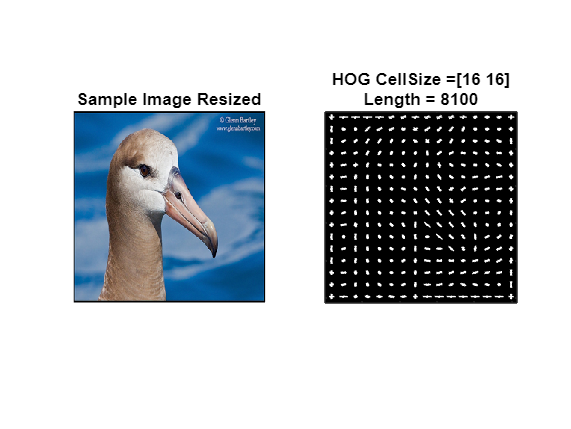

hogFeatureSize = 8100

hogFeatureSize = showImageFeatures(trainCDS, true, cellSize)

disp("HOG feature size is " + hogFeatureSize)

HOG feature size is 8100


## Extract HOG Features

trainFeatures = extractHOGFeaturesFromDatastore(trainCDS, hogFeatureSize, cellSize)

trainFeatures = 7057×8100 single matrix
    0.3903    0.0455    0.0357    0.0711    0.3903    0.1066    0.0620    0.0424    0.3903    0.3903    0.0467    0.0471    0.0329    0.0794    0.0364    0.0363    0.0324    0.3903    0.0280    0.0322    0.0487    0.0775    0.3903    0.0850    0.0548    0.0273    0.0260    0.0368    0.0411    0.0614    0.0419    0.0929    0.0357    0.0493    0.0302    0.0358    0.4247    0.0926    0.1005    0.0639    0.1697    0.0557    0.0530    0.0601    0.4247    0.4247    0.0684    0.1009    0.0690    0.1466
    0.4075    0.0036    0.0046    0.0067    0.4075    0.0386    0.0080    0.0320    0.4075    0.4075    0.0052    0.0076    0.0005    0.0155    0.0017    0.0095    0.0063    0.4075    0.0093    0.0033    0.0052    0.0026    0.4075    0.0016    0.0058    0.0030    0.0091    0.0081    0.0028    0.0053    0.0010    0.0122    0.0005    0.0057    0.0026    0.0080    0.4990    0.0112    0.0158    0.0006    0.0297    0.0031    0.0152    0.0108    0.4990    0.499

testFeatures = extractHOGFeaturesFromDatastore(testCDS, hogFeatureSize, cellSize)

testFeatures = 2360×8100 single matrix
    0.1316    0.1020    0.1088    0.2585    0.2585    0.2578    0.1238    0.0923    0.1561    0.1091    0.1373    0.1231    0.1664    0.2585    0.2585    0.1624    0.1178    0.1021    0.0685    0.0860    0.1080    0.2585    0.2585    0.2585    0.1380    0.0889    0.0649    0.0909    0.0704    0.0817    0.1651    0.2374    0.2215    0.1694    0.1006    0.0865    0.0898    0.1292    0.1111    0.2005    0.2423    0.2423    0.1744    0.1040    0.0779    0.1196    0.1406    0.1305    0.2423    0.2423
    0.1028    0.0873    0.0251    0.0328    0.0984    0.0396    0.0333    0.1610    0.1435    0.1913    0.1568    0.0803    0.1049    0.2545    0.1490    0.0823    0.2545    0.2545    0.2256    0.1474    0.0510    0.0770    0.2545    0.0885    0.0439    0.0828    0.2171    0.2545    0.2545    0.1295    0.1684    0.2545    0.2226    0.1269    0.1995    0.2545    0.2092    0.1676    0.0987    0.1253    0.2486    0.2129    0.1112    0.2486    0.2486    0.0964

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7439773696 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train classifier

SVMClassifier = trainSVMClassifier(gpuArray(trainFeatures), trainingImageDS.Labels);

## **Hyper Params**

SVMClassifier

SVMClassifier =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [001    002    003    004    005    006    007    008    009    010    011    012    013    014    015    016    017    018    019    020    021    022    023    024    025    026    027    028    …    ] (1×200 categorical)
           ScoreTransform: 'none'
           BinaryLearners: {200×1 cell}
               CodingName: 'onevsall'


  Properties, Methods


## Evaluate

[accuracy, predictions] = evaluateClassifier(SVMClassifier, testFeatures, testImageDS.Labels);

## Plot confusion matrix

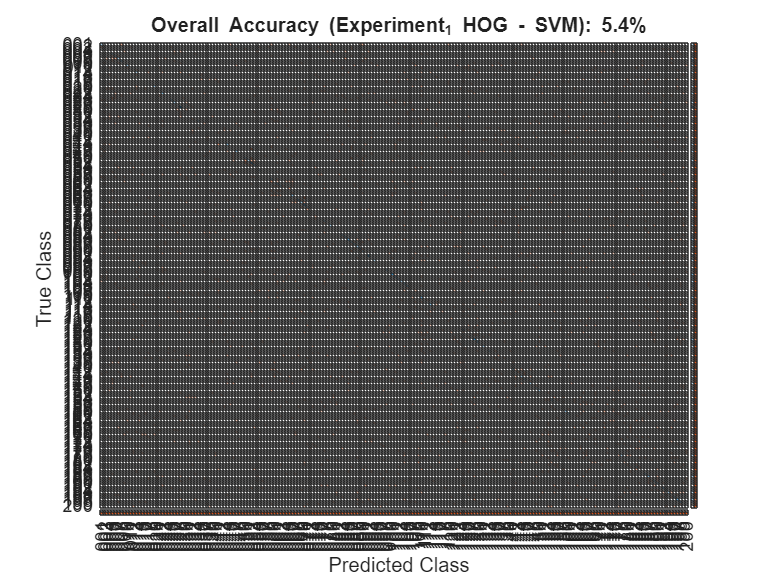

Classwise Recognition Rates:
    8.3000
         0
         0
         0
   11.1000
   12.5000
    8.3000
   22.2000
         0
    8.3000
         0
         0
    8.3000
         0
         0
         0
         0
         0
    8.3000
         0
         0
   18.2000
         0
         0
    8.3000
    8.3000
         0
   58.3000
         0
         0
         0
         0
         0
    8.3000
         0
         0
         0
         0
         0
         0
         0
         0
         0
   16.7000
         0
         0
   16.7000
         0
         0
    8.3000
    8.3000
   41.7000
   16.7000
         0
    8.3000
         0
         0
         0
    8.3000
         0
   16.7000
    8.3000
         0
         0
         0
   16.7000
         0
   25.0000
    8.3000
   33.3000
    8.3000
         0
         0
         0
         0
         0
    8.3000
         0
    8.3000
         0
         0
         0
    8.3000
   16.7000
   25.0000
    8.3000
    8.3000
    8.3000
   

plotConfusionMatrix(testImageDS.Labels, predictions, "Overall Accuracy (Experiment_1 HOG - SVM): " + string(round(accuracy*100, 1)) + "%");